Ch5 数字滤波器设计

巴特沃斯模拟滤波器振幅特性与对阶数N的依赖关系

课本P178 图2 -23

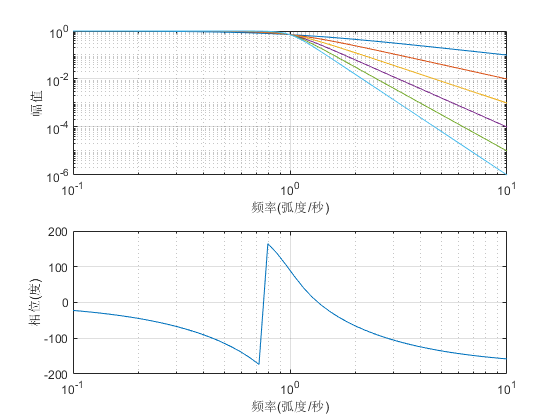

     1



     0     1



     1     1



     2



     0     0     1



    1.0000    1.4142    1.0000



     3



         0         0         0    1.0000



    1.0000    2.0000    2.0000    1.0000



     4



     0     0     0     0     1



    1.0000    2.6131    3.4142    2.6131    1.0000



     5



     0     0     0     0     0     1



    1.0000    3.2361    5.2361    5.2361    3.2361    1.0000



     6



     0     0     0     0     0     0     1



    1.0000    3.8637    7.4641    9.1416    7.4641    3.8637    1.0000



clear; 
close all;
clc;

%--------------------------------------------------------------------------
%官网程序，幅度按dB，叠加显示
%--------------------------------------------------------------------------
figure;
N = 6;
for n = 1:N
    [z, p, k]=buttap(n);
    [num,den] = zp2tf(z,p,k);
    W = logspace(-1,1);
    freqs(num,den,W)                % Frequency response of analog filter
    hold on;
    
    hs = tf(num,den);
    
    %课本 P179 表5-1；但归一化Wc
    %打印输出显示阶数
    disp(n);
    %打印输出显示分子
    disp(num);
    %打印输出显示分母
    disp(den);
    %打印输出显示系统函数
    hs;   
end

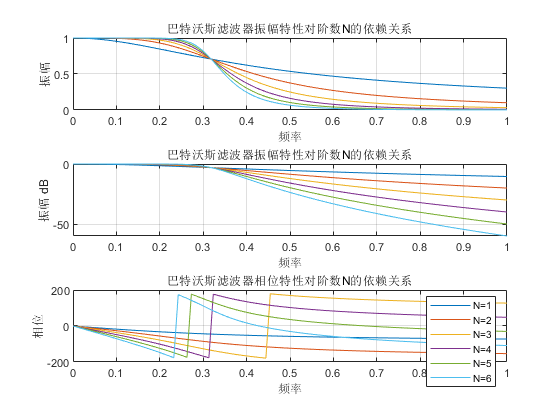

%--------------------------------------------------------------------------
%在官网程序基础上，幅度按线性，叠加显示
%--------------------------------------------------------------------------
figure;
N = 6;
str = ["N=1","N=2","N=3","N=4","N=5","N=6"];
for n = 1:N
    [z, p, k]=buttap(n);
    [num,den] = zp2tf(z,p,k);
    w = linspace(0, pi);        
    h = freqs(num,den,w);
    mag = abs(h)/abs(h(1));
    dbmag = 20*log10(mag);
    phase = angle(h);           %输出scale:-pi~pi
    degphase = phase*180/pi;    %转为degree

    subplot(3,1,1), plot(w/pi,mag)
    xlabel('频率');
    ylabel('振幅');
    title('巴特沃斯滤波器振幅特性对阶数N的依赖关系')
    grid on;
    hold on;
    
    subplot(3,1,2), plot(w/pi,dbmag)
    xlabel('频率');
    ylabel('振幅 dB');
    title('巴特沃斯滤波器振幅特性对阶数N的依赖关系')
    grid on;
    hold on;
    
    subplot(3,1,3), plot(w/pi,degphase)
    xlabel('频率');
    ylabel('相位');
    title('巴特沃斯滤波器相位特性对阶数N的依赖关系')
    grid on;
    hold on;
end
legend(str(1),str(2),str(3),str(4),str(5),str(6));

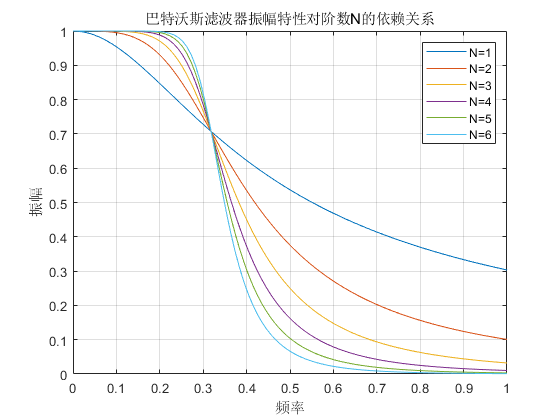

%--------------------------------------------------------------------------
%单独把幅度拿出来显示
%--------------------------------------------------------------------------
figure;
N = 6;
str = ["N=1","N=2","N=3","N=4","N=5","N=6"];
for n = 1:N
    [z, p, k]=buttap(n);
    [num,den] = zp2tf(z,p,k);
    w = linspace(0, pi);        
    h = freqs(num,den,w);
    mag = abs(h)/abs(h(1));
    dbmag = 20*log10(mag);
    phase = angle(h);           %输出scale:-pi~pi
    degphase = phase*180/pi;    %转为degree

    plot(w/pi,mag)
    xlabel('频率');
    ylabel('振幅');
    title('巴特沃斯滤波器振幅特性对阶数N的依赖关系')
    grid on;
    hold on;   
end
legend(str(1),str(2),str(3),str(4),str(5),str(6));